# Code MATLAB Response to Data Change in JavaScript

Create an `htmlComponent` JavaScript® object that generates a random number when a button is clicked, and display the number in MATLAB®.

First, create an empty HTML UI component and position it within a figure.

fig = uifigure;
fig.Position = [500 500 490 180];

h = uihtml(fig);
h.Position = [20 20 450 130];

Then, create an HTML file called `generateJSRandomNumber.html`. In the file, 

- Use a `style` tag to define internal CSS styles for a button element.

- Write a `setup` function inside of a `<script>` tag to connect your JavaScript object, called `htmlComponent`, to the HTML UI component you created in MATLAB.

- Add an event listener within the `setup` function. The event listener listens for `"click"` events on the button and creates a listener callback function. When a click event occurs, the listener callback function sets the `Data` property of the `htmlComponent` JavaScript object to a randomly generated integer between `1` and `100`.

Now, in MATLAB, set the value of the `HTMLSource` property to the path to the HTML file. Create a `DataChangedFcn` callback function that displays the random number your JavaScript code generates. Click the **Generate Random Number** button to see the value of the `Data` property display in the MATLAB Command Window.

h.HTMLSource = fullfile(pwd,'generateJSRandomNumber.html');
h.DataChangedFcn = @(src,event)disp(h.Data);

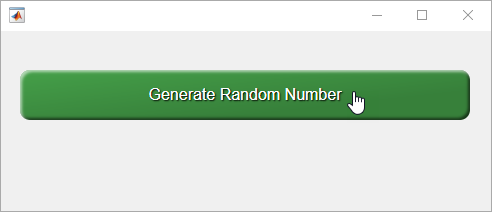

*Copyright 2019 The MathWorks, Inc.*